# Proyecto de ciencia de los datos

## Universidad Autónoma del Estado de México

## CU UAEM Zumpango

## Ingeniería en Computación

## Ciencia de los Datos

## Integrantes:

**    -Ernesto Martinez Islas**

**    -Cesar Augusto Ramirez Adan**

**    -Kevin Alain Rodriguez Cruz**

## Profesor: Asdrúbal López Chau

## Noviembre 2022

## Conjunto de datos

Los datos analizados para este trabajo fueron recopilados de estadísticas de futbol. Aquí podemos encontrar datos como: Nombre, Minutos Jugados, Asistencias, posición, Equipo, Edad y Goles. De modo que se recopilo las actuaciones de cada jugador por individual, permitiéndonos separar: ataque, defensa, pases y duelos individuales.

El ataque suele referirse a los tiros al arco, tanto acertados como fallados; las acciones defensivas engloban algunas como intercepciones o tiros bloqueados.

En un partido, los pases pueden ser: efectivos o fallados.

## Preguntas 

1.¿Se puede obtener su prime (mejor momento) de un jugador con los datos?

R= Si, podemos obtenerlo mediante la relación de su número de goles y asistencias, también depende de su posición. Lo sabremos mediante la posición, debido a que si es delantero deben contar con un mayor número de goles y por el contrario si es un jugador en la posición de medio debe contar con mayor número de asistencias a gol.

2.¿Se puede obtener cuando un jugador esta apunto de retirarse?

R= Para poder responder a esta pregunta debemos encontrar una relación de cada jugador y sus minutos jugados por partido, esto se hace porque un jugador cuando esta apunto de retirarse suele reducir gradualmente sus minutos, de esta manera podremos encontrar una aproximación y poder predecir si un jugador esta apunto de retirarse o no.

3.¿Se puede obtener cuando un jugador es más longevo?

R= Para poder resolver esta hipótesis planteada, debemos analizar apariciones por partido de los jugadores por individual, así como los minutos jugados y además de su posición, así podremos encontrar una relación y afirmar si un jugador es más longevo. 

4.¿Se puede obtener el equipo más efectivo en goles?

R= Si, podemos obtenerlo mediante una sumatoria total de goles anotados por jugador de manera individual.

5.¿Se podría obtener el equipo más efectivo en asistencias?

R= De igual forma que la pregunta anterior podremos realizar o tratar de afirmas esta hipótesis mediante la suma total de todas las asistencias por jugador de cada equipo.

## Análisis Exploratorio

%Leemos la tabla
P = readtable("Premier_League_players.csv")

P = 537×13 table
    x_           Player                    Team             Apps    Min     G     A           xG                xA          xG90    xA90     Pos      Edad
    __    _____________________    _____________________    ____    ____    __    __    ______________    ______________    ____    ____    ______    ____

     1    {'Son Heung-Min'    }    {'Tottenham'        }     35     3051    23     7    {'16.99-6.01'}    {'7.85+0.85' }     0.5    0.23    {'st'}     38 
     2    {'Mohamed Salah'    }    {'Liverpool'        }     35     2757   

%Categorizamos posicion y ID
P.Pos = categorical(P.Pos)

P = 537×13 table
    x_           Player                    Team             Apps    Min     G     A           xG                xA          xG90    xA90    Pos    Edad
    __    _____________________    _____________________    ____    ____    __    __    ______________    ______________    ____    ____    ___    ____

     1    {'Son Heung-Min'    }    {'Tottenham'        }     35     3051    23     7    {'16.99-6.01'}    {'7.85+0.85' }     0.5    0.23    st      38 
     2    {'Mohamed Salah'    }    {'Liverpool'        }     35     2757    23    13

P.x_ = categorical(P.x_)

P = 537×13 table
    x_           Player                    Team             Apps    Min     G     A           xG                xA          xG90    xA90    Pos    Edad
    __    _____________________    _____________________    ____    ____    __    __    ______________    ______________    ____    ____    ___    ____

    1     {'Son Heung-Min'    }    {'Tottenham'        }     35     3051    23     7    {'16.99-6.01'}    {'7.85+0.85' }     0.5    0.23    st      38 
    2     {'Mohamed Salah'    }    {'Liverpool'        }     35     2757    23    13

%Eliminamos datos falatantes
P = rmmissing(P)

P = 537×13 table
    x_           Player                    Team             Apps    Min     G     A           xG                xA          xG90    xA90    Pos    Edad
    __    _____________________    _____________________    ____    ____    __    __    ______________    ______________    ____    ____    ___    ____

    1     {'Son Heung-Min'    }    {'Tottenham'        }     35     3051    23     7    {'16.99-6.01'}    {'7.85+0.85' }     0.5    0.23    st      38 
    2     {'Mohamed Salah'    }    {'Liverpool'        }     35     2757    23    13

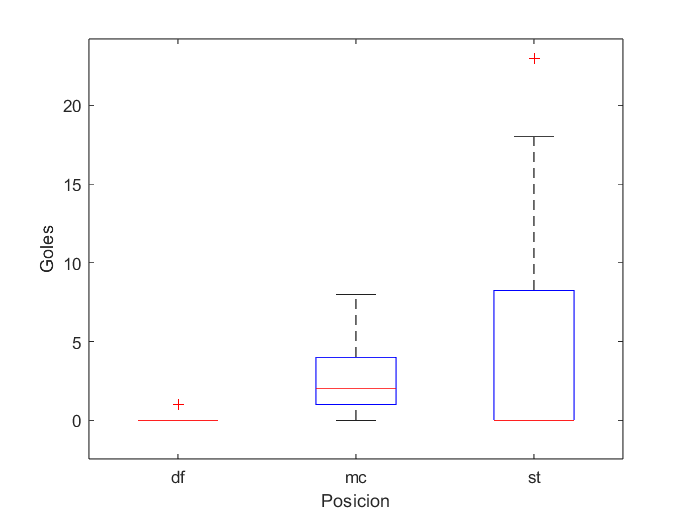

%Graficamos con un box plot la realacion que exite entre
%Goles Anotados en relacion a la posiciones que juegan
boxplot(P.G,P.Pos)
ylabel("Goles"),xlabel("Posicion") 

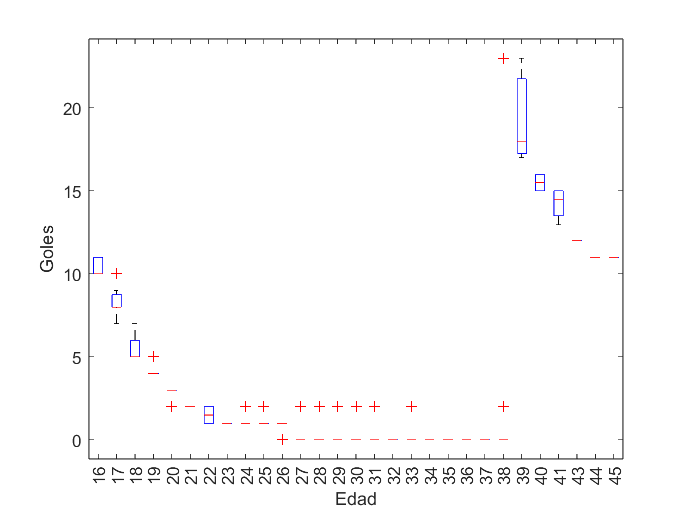


%Graficamos con un box plot la realacion que exite entre
%Goles Anotados en relacion a la edad
boxplot(P.G,P.Edad)
ylabel("Goles"),xlabel("Edad")

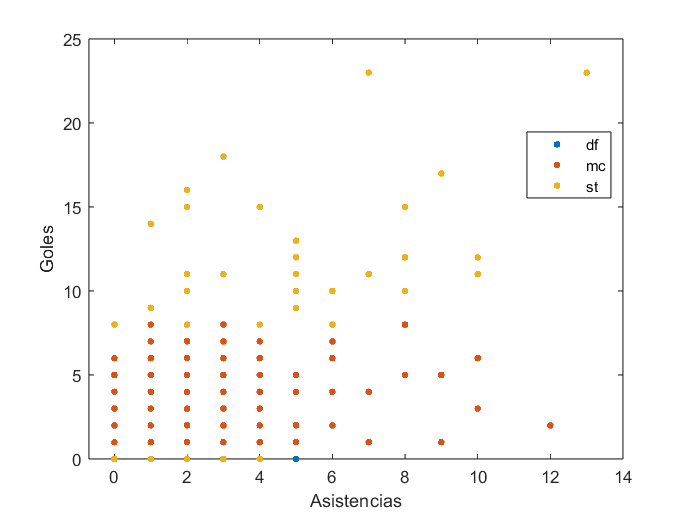


%Graficamos con un box plot la realacion que exite entre
%Goles Anotados en relacion a las asistencias
gscatter(P.A,P.G,P.Pos)
xlabel("Asistencias")
ylabel("Goles")

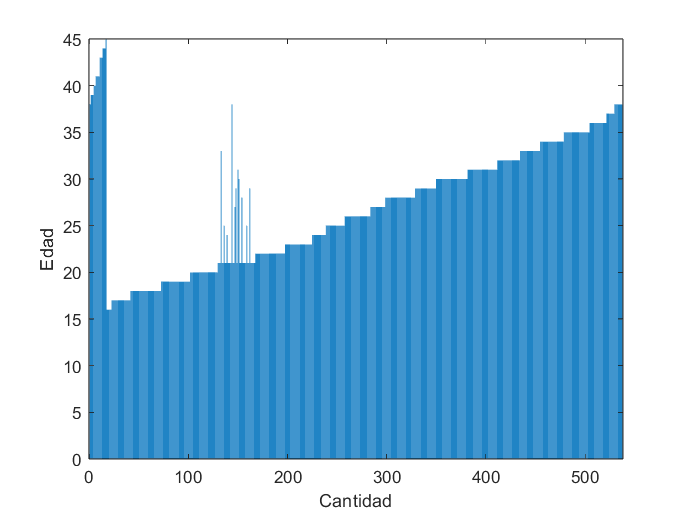


%--------------------
bar(P.Edad)
xlabel("Cantidad")
ylabel("Edad")

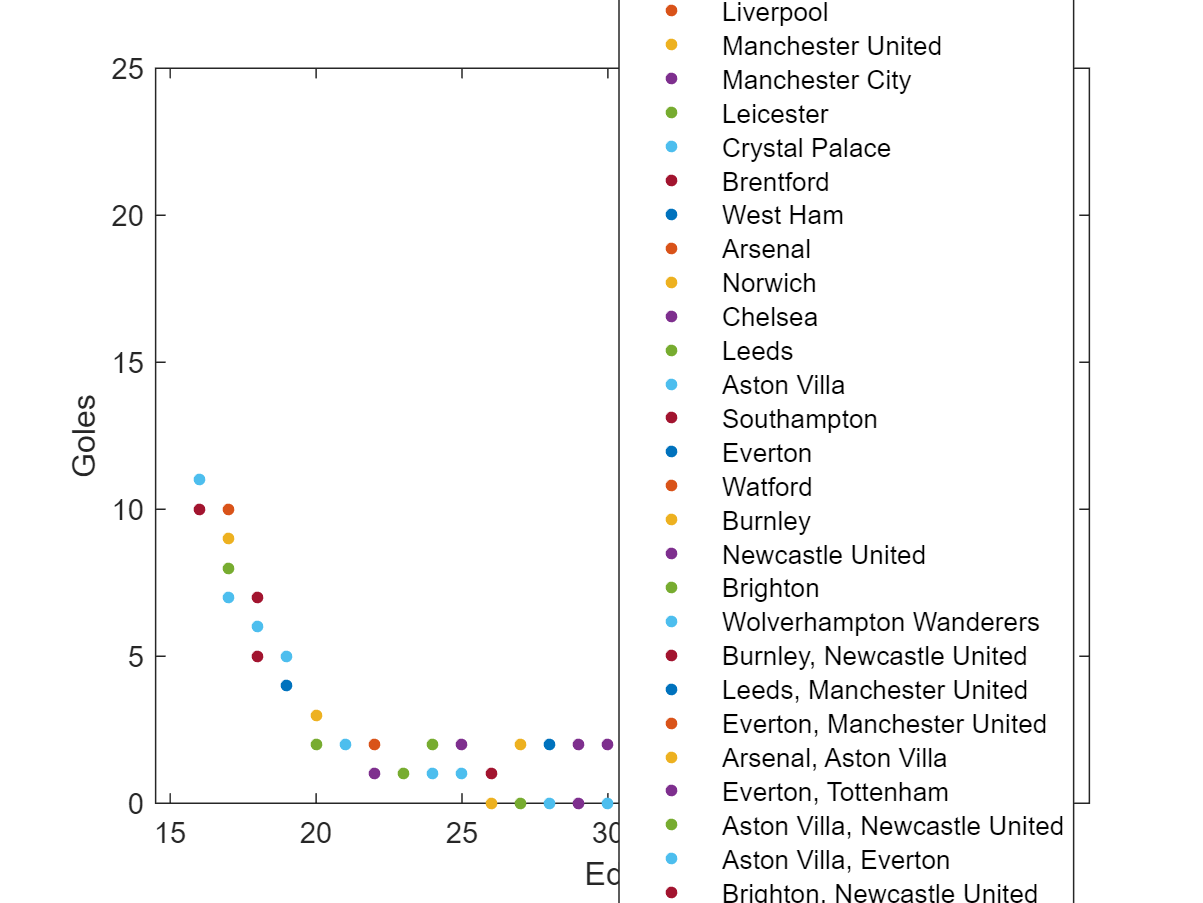

%--------------------

gscatter(P.Edad,P.G,P.Team)
xlabel("Edad")
ylabel("Goles")

xlim([14.5 46.5])
ylim([0.0 25.0])
legend("Position",[0.78562,0.034762,0.37143,1.0417])

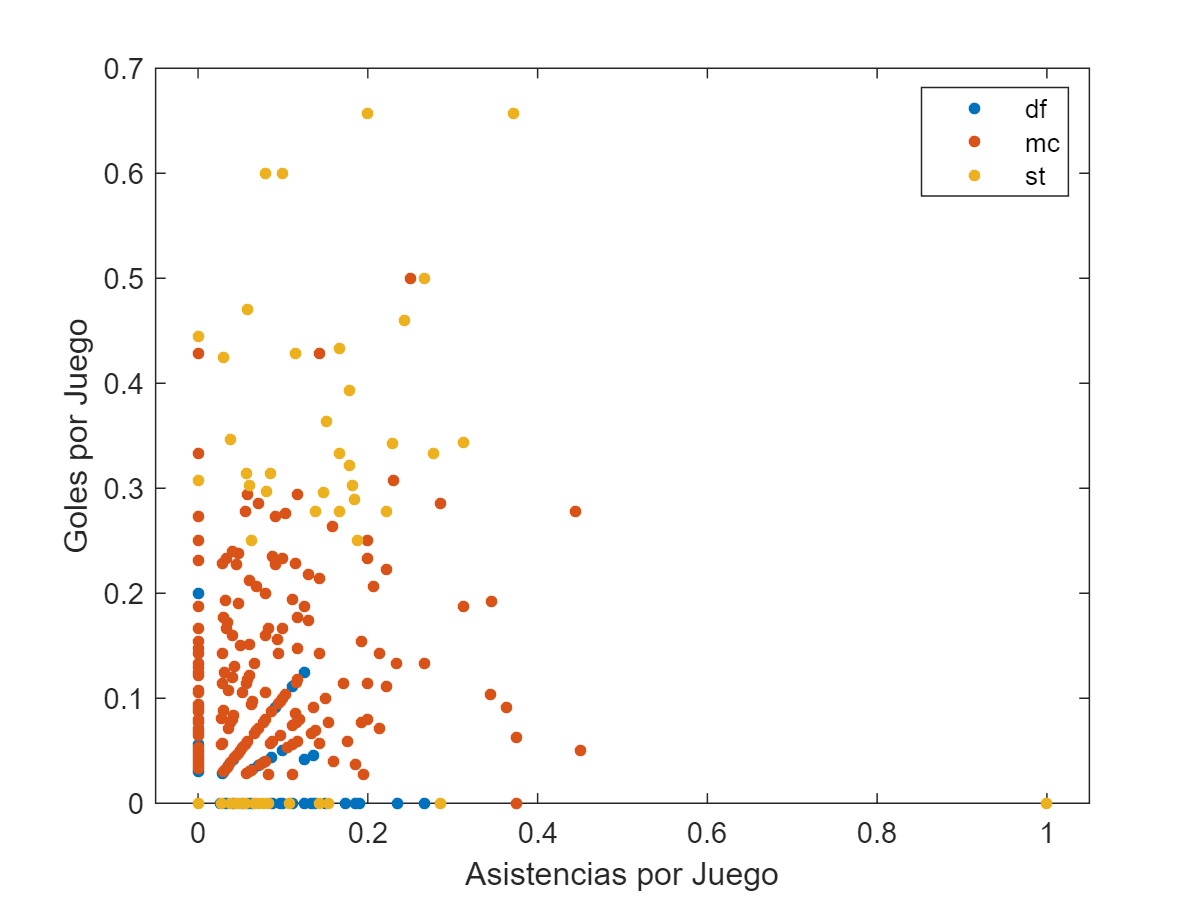



gscatter(P.A./P.Apps,P.G./P.Apps,P.Pos)
xlabel("Asistencias por Juego")
ylabel("Goles por Juego")

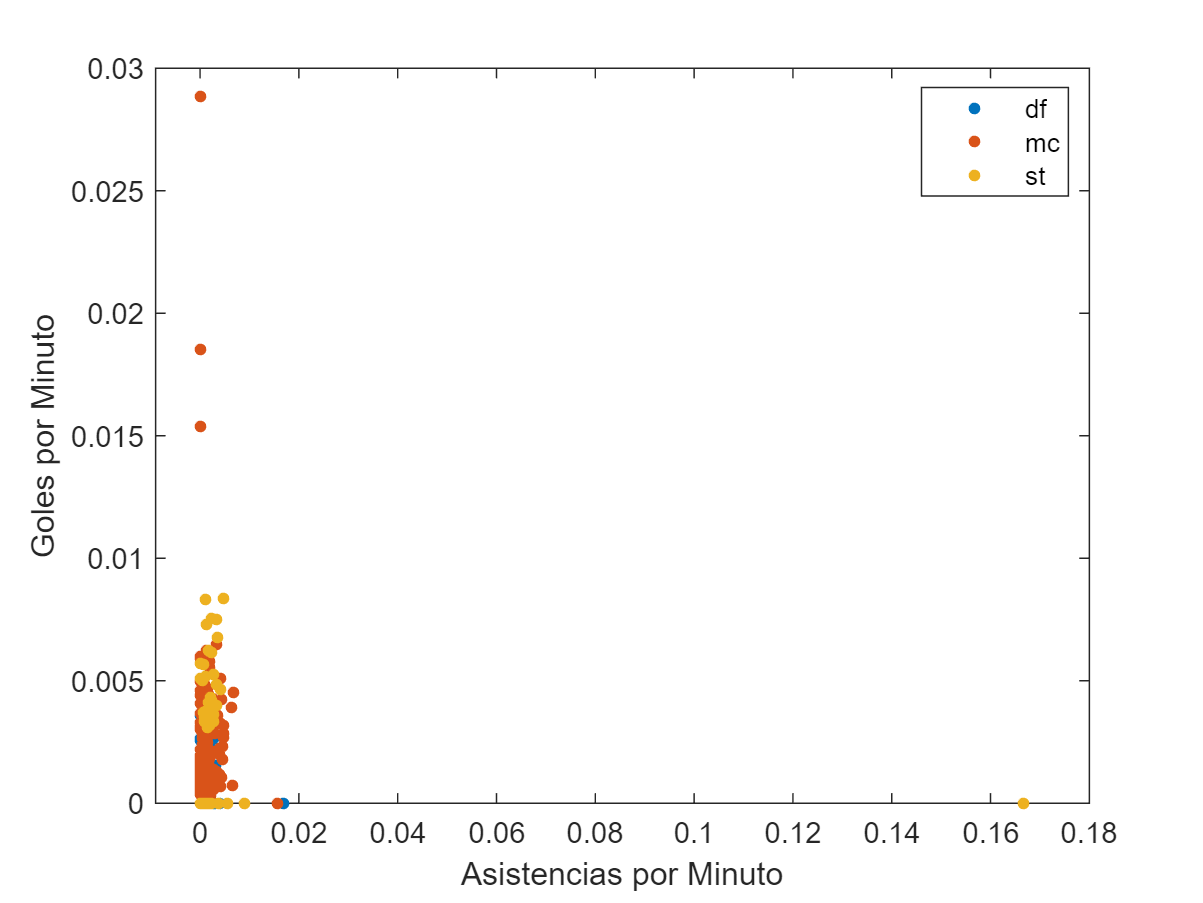

%------------------------
gscatter(P.A./P.Min,P.G./P.Min,P.Pos)
xlabel("Asistencias por Minuto")
ylabel("Goles por Minuto")

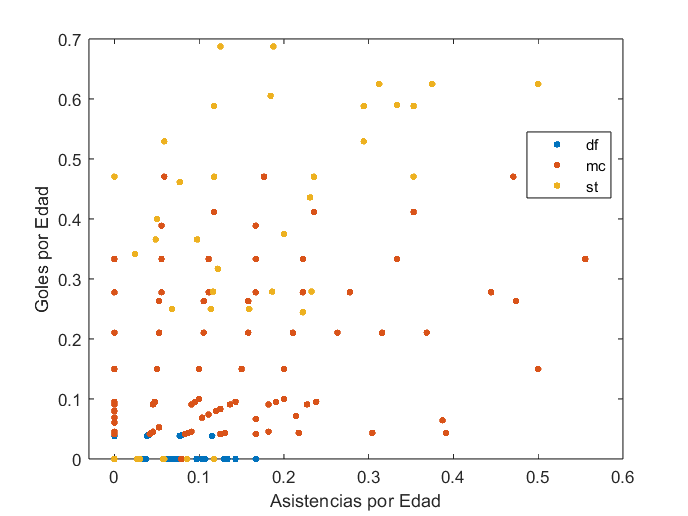


%------------------------
gscatter(P.A./P.Edad,P.G./P.Edad,P.Pos)
xlabel("Asistencias por Edad")
ylabel("Goles por Edad")

## Análisis de los datos

Aplicar los métodos necesarios.

%Media, mediana y moda de los datos utilizados

%Media
pjprom = mean(P.Apps)

pjprom = 19.5251

minJprom = mean(P.Min)

minJprom = 1.3994e+03

gprom = mean(P.G)

gprom = 1.9311

aprom = mean(P.A)

aprom = 1.3836

eprom = mean(P.Edad)

eprom = 27.0186


%Mediana
pjmed = median(P.Apps)

pjmed = 21

minJmed = median(P.Min)

minJmed = 1356

gmed = median(P.G)

gmed = 1

amed = median(P.A)

amed = 1

emed = median(P.Edad)

emed = 27




%Moda
pjmod = mode(P.Apps)

pjmod = 1

minJmod = mode(P.Min)

minJmod = 1

gmod = mode(P.G)

gmod = 0

amod = mode(P.A)

amod = 0

emod = mode(P.Edad)

emod = 30

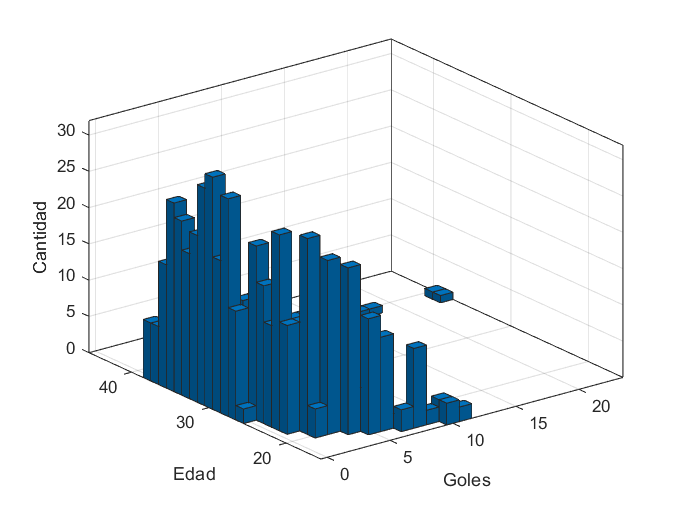


histogram2(P.G,P.Edad)
xlabel('Goles')
ylabel('Edad')
zlabel("Cantidad")

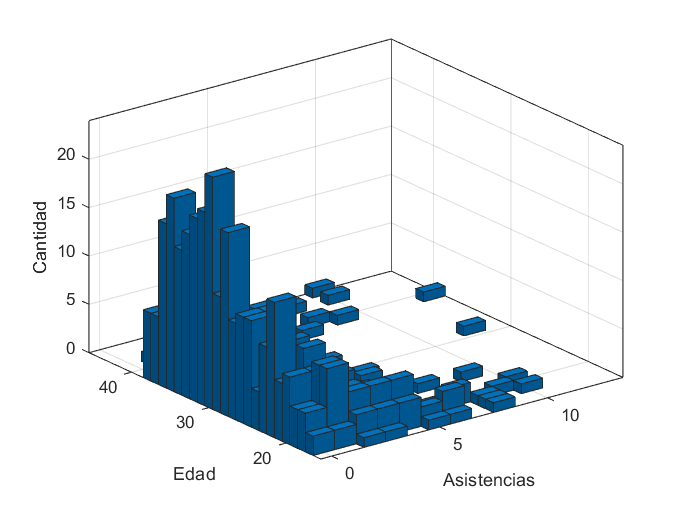


histogram2(P.A,P.Edad)
xlabel('Asistencias')
ylabel('Edad')
zlabel("Cantidad")

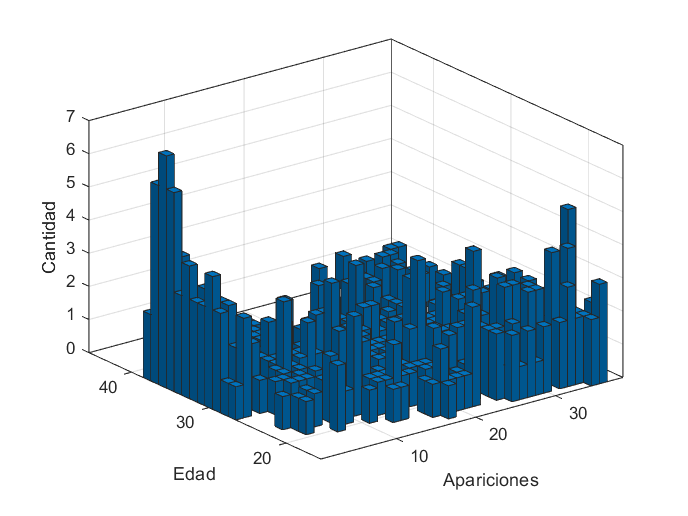


histogram2(P.Apps,P.Edad)
xlabel('Apariciones')
ylabel('Edad')
zlabel("Cantidad")

%Coeficiente De R De Pearson
r1 = corr(P.G,P.Apps,'Type','Pearson')

r1 = 0.4802

r2 = corr(P.Edad,P.G,'Type','Pearson')

r2 = -0.2169

r3 = corr(P.Edad,P.Min,'Type','Pearson')

r3 = -0.3582

r4 = corr(P.Edad,P.Apps,'Type','Pearson')

r4 = -0.4295


fitrlinear(P.G,P.Apps, "Learner","svm")

ans =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: 1.7886
                 Bias: 16.5561
               Lambda: 0.0019
              Learner: 'svm'


  Properties, Methods


## Hallazgos

Mediante los grafos podemos observar las relaciones que existen entre algunas de las variables, por ejemplo; en la primera grafica podemos observar que las posiciones influyen en los goles que se anotan, debido a que los delanteros tienen mayor número de goles, por otro lado tenemos otra grafica que nos indica la relación que existe entre el número de asistencias con la posiciones y podemos observar que el mayor número de asistencias las obtienen los medios, mediante las gráficas podemos obtener una visón más clara de las situaciones y vemos que cada jugar jugador cumple una función dentro del equipo y así podemos sacarle provecho a cada uno de los jugadores.

después para poder en meter la relación que existe entre variables pudimos aplicar los distintos análisis a los datos para encontrar hallazgos. Nosotros implementamos el coeficiente de correlación de Pearson que es una prueba que mide la relación estadística entre dos variables continuas. Si la asociación entre los elementos no es lineal, entonces el coeficiente no se encuentra representado adecuadamente.

El coeficiente de correlación de Pearson tiene el objetivo de indicar cuán asociadas se encuentran dos variables entre sí por lo que:

**Correlación menor a cero: **Si la correlación es menor a cero, significa que es negativa, es decir, que las variables se relacionan inversamente.

Cuando el valor de alguna variable es alto, el valor de la otra variable es bajo. Mientras más próximo se encuentre a -1, más clara será la covariación extrema. Si el coeficiente es igual a -1, nos referimos a una correlación negativa perfecta.

**Correlación mayor a cero: **Si la correlación es igual a +1 significa que es positiva perfecta. En este caso significa que la correlación es positiva, es decir, que las variables se correlacionan directamente.

Cuando el valor de una variable es alto, el valor de la otra también lo es, sucede lo mismo cuando son bajos. Si es cercano a +1, el coeficiente será la covariación.

**Correlación igual a cero:** Cuando la correlación es igual a cero significa que no es posible determinar algún sentido de covariación. Sin embargo, no significa que no exista una relación no lineal entre las variables.

Cuando las variables son independientes significa que estas se encuentran correlacionadas, pero esto no significa que el resultado sea verdadero.

## Conclusiones

%Coeficiente De R De Pearson
%r1 = 0.4802
%r2 = -0.2169
%r3 = -0.3582
%r4 = -0.4295

Podemos concluir que los modelos empleados para esta situación pueden servir para que los equipos mejor su rendimiento, hacer planes de entrenamiento mejor personalizados a los jugadores, Y por supuesto todo esto debe ayudar a ganar títulos.

Pero, más allá de lo técnico, encontraremos dinero de por medio. Las casas de apuestas y sus clientes han empezado a tomar nota del funcionamiento del big data y los modelos predictivos usados para avisar posibles estadísticas.